clc; clearvars;
addpath overlap_functions\

z = linspace(1,5e3,1e2);
r = linspace(0,6,1e3); % distance from telescope OA, change so max distance is based on telescope FOV
theta = linspace(0,2*pi,1e2);

z_km = z./1000;

[rG,zG,tG] = meshgrid(r,z,theta);

delta = 0.5;

rpG = sqrt(rG.^2 + delta^2 - 2*delta.*rG.*cos(tG)); % distance to laser axis in terms of distance to and angle about telescope axis

laser_beamwaist = 1.5e-3; % w0
laser_divergence = .5e-3; % phi0

telescope_radius = .2; % R
telescope_focus = 5; % f
% telescope_fov = 2 * telescope_radius / telescope_focus; % phi1
telescope_fov = 1e-3;

r1 = coneRadius(telescope_radius,telescope_fov,z);
r2 = laserBeamWidth(laser_beamwaist,laser_divergence,z);

Show simplified overlap function determined by overlap between laser beam cross section and telescope FOV 

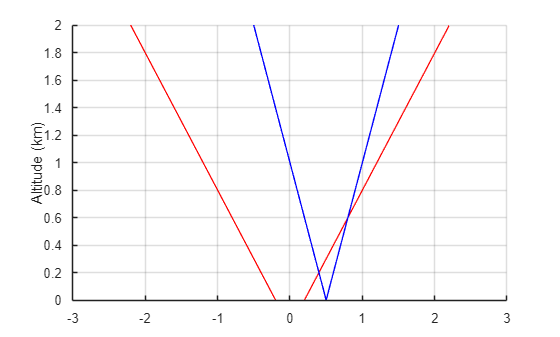

A_overlap = circleOverlap(r1,r2,repmat(delta,1,length(r1)));

figure;
hold on;
plot(r1,z_km,'r')
plot(-r1,z_km,'r')

plot(delta+r2, z_km,'b')
plot(delta+-r2, z_km,'b')

hold off
ylabel("Altitude (km)")
grid on

% xlim([-.5 5])
ylim([0 2])

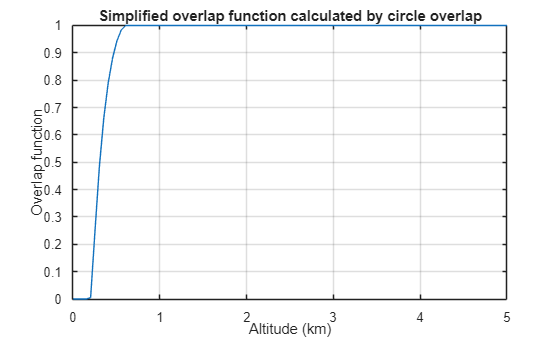

figure;
plot(z_km,A_overlap./(pi.*r2.^2));
ylabel("Overlap function")
xlabel("Altitude (km)")
title("Simplified overlap function calculated by circle overlap")
grid on

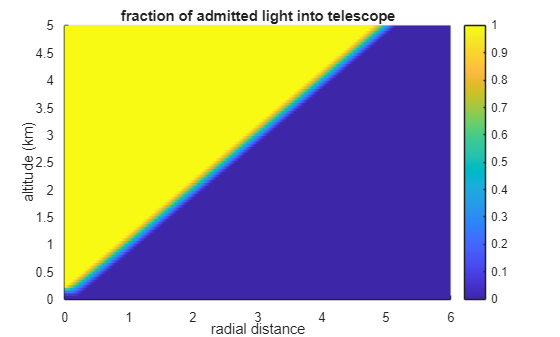

a = 5e-3;
b = 0;
zap = 0;

psi = overlapFunc(a,b,telescope_radius,telescope_focus,r,zap,z);

figure
s = surf(rG(:,:,1),zG(:,:,1)./1000,psi);
s.EdgeColor = 'none';
xlabel('radial distance')
ylabel('altitude (km)')
title('fraction of admitted light into telescope')
colorbar
clim([0 1])
view(0,90)

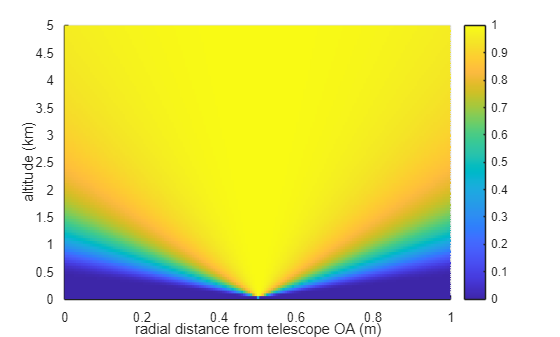

w = laserBeamWidth(laser_beamwaist,laser_divergence,zG);

P0 = 1;
f = laserProfile(w,rpG,"gaussian");
% f = laserProfile(w,rpG,"rectangular");

figure
s = surf(rG(:,:,1),zG(:,:,1)./1000,f(:,:,1));
s.EdgeColor = 'none';
xlabel('radial distance from telescope OA (m)')
ylabel('altitude (km)')
title('')
view(0,90)
colorbar
clim([0 P0])
xlim([0 1])

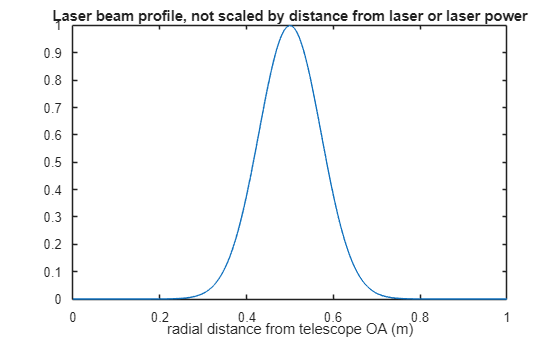

zi = 5;
figure;
plot(rG(zi,:,1),f(zi,:,1))
xlim([0 1])
xlabel("radial distance from telescope OA (m)")
% ylabel("Irradiance")
title("Laser beam profile, not scaled by distance from laser or laser power")

O = NaN(1,length(z));
for i = 1:length(z)
    z_current = z(i);
    w_current = laserBeamWidth(laser_beamwaist,laser_divergence,z_current);

    O(i) = (1/(pi * w_current^2)) * integral2(@(r,theta) fun(r, theta, z_current, laser_beamwaist, laser_divergence, a, b, telescope_radius, telescope_focus, zap, delta, 'gaussian'), 0, Inf, 0, 2*pi);
end

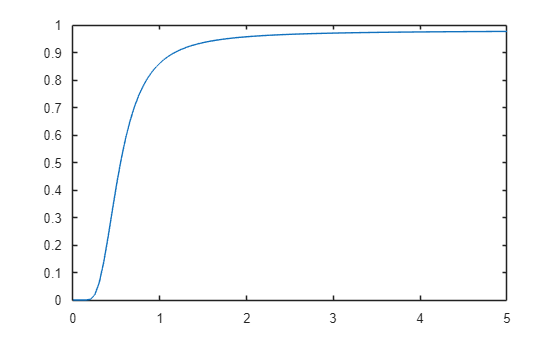

figure;
plot(z_km,O)

function A = fun(r,theta,z,w0,phi,a,b,R,f,zap,delta,prof_type)
    w = laserBeamWidth(w0,phi,z);

    rp = @(r,theta,delta) sqrt(r.^2 + delta^2 - 2*delta.*r.*cos(theta));

    F =  laserProfile(w,rp(r,theta,delta),prof_type);

    psi = overlapFunc(a,b,R,f,r,zap,z);

    A = psi .* F .* r;
end